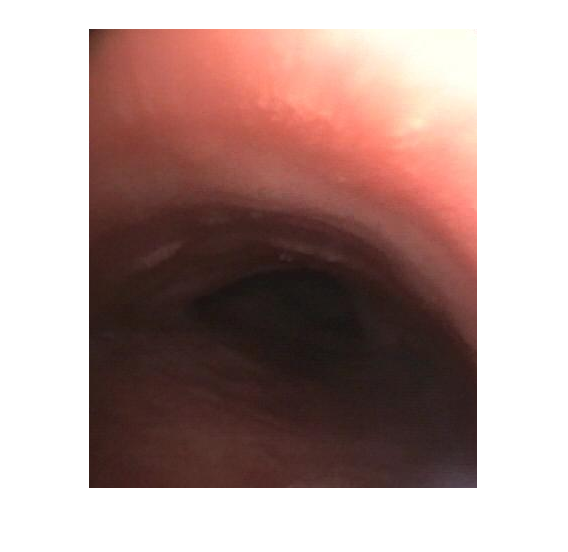

I1 = imread('400.jpg');
I112 = imread('79.jpg');

I1 = imcrop(I1,[168,54,387,458]);
I112 = imcrop(I112,[168,54,387,458]);

imshow(I1)

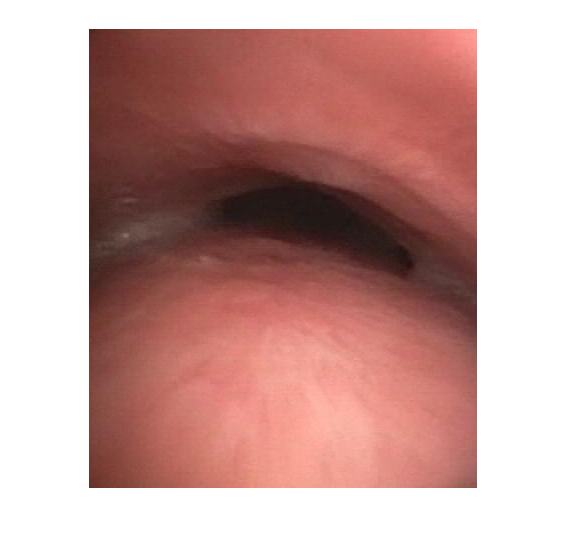

imshow(I112)

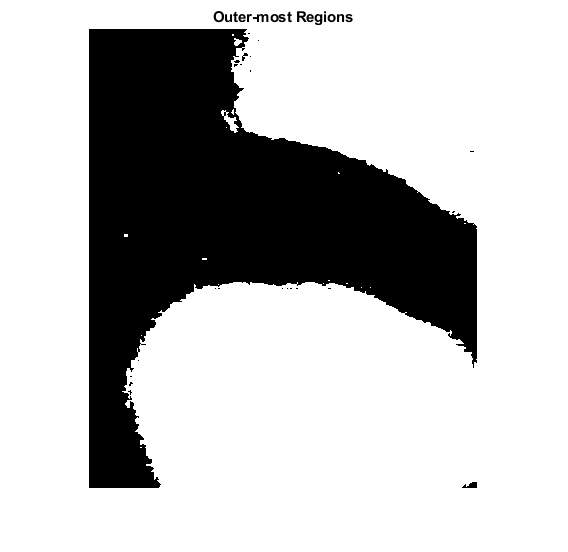


I1RChannel = I1(:,:,1);
I1GChannel = I1(:,:,2);
I1BChannel = I1(:,:,3);

I112RChannel = I112(:,:,1);
I112GChannel = I112(:,:,2);
I112BChannel = I112(:,:,3);

% ------------ Watershed Kmeans ---------------

    [maximums, ~, ~, ~] = kmeansRGBSegmentation(I112, 2, 1);
    figure
    imshow(maximums)
    title('Outer-most Regions')

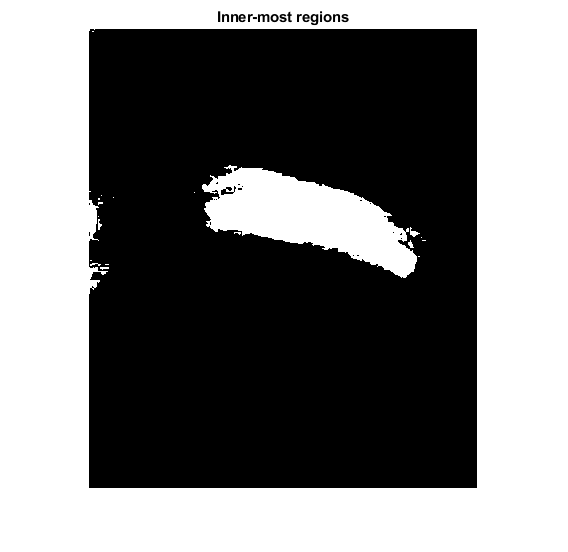

    
    imGray = rgb2gray(I112);
    grayProcessed = openCloseByReconstruction(imGray);
    
    minimas = imregionalmin(grayProcessed);
    
    maximas = imregionalmax(grayProcessed);
    
    minimums= kmeansRGBSegmentation(I112, 8, 0);
    figure
    imshow(minimums)
    title('Inner-most regions')

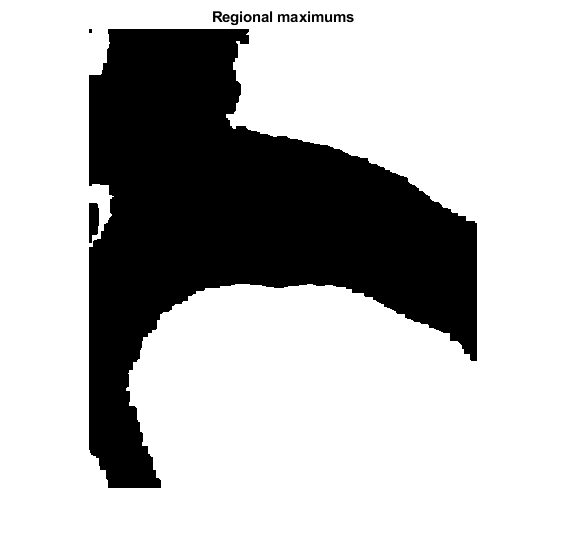

    
    minimas = minimas & ~minimums;
    maximums = maximums | minimas | maximas;
    
    se = strel(ones(5,5));
    minimums = imclose(minimums,se);
    minimums = imerode(minimums,se);
    minimums = bwareaopen(minimums,50);
    
    maximums = imclose(maximums,se);
    maximums = imerode(maximums,se);
    maximums = bwareaopen(maximums,50);
    
    figure
    imshow(maximums)
    title('Regional maximums')

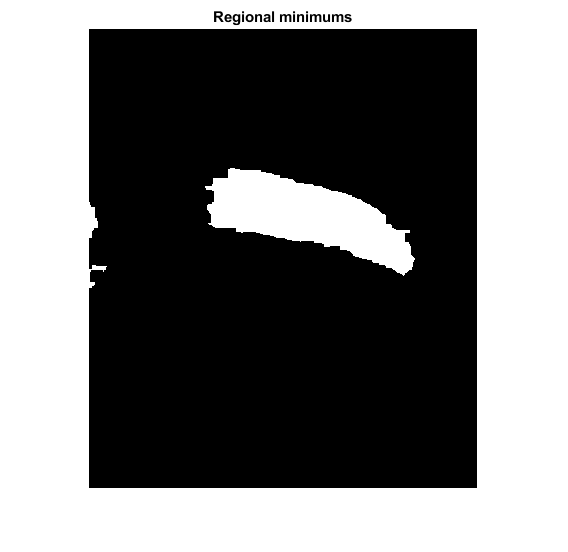

    
    figure
    imshow(minimums)
    title('Regional minimums')

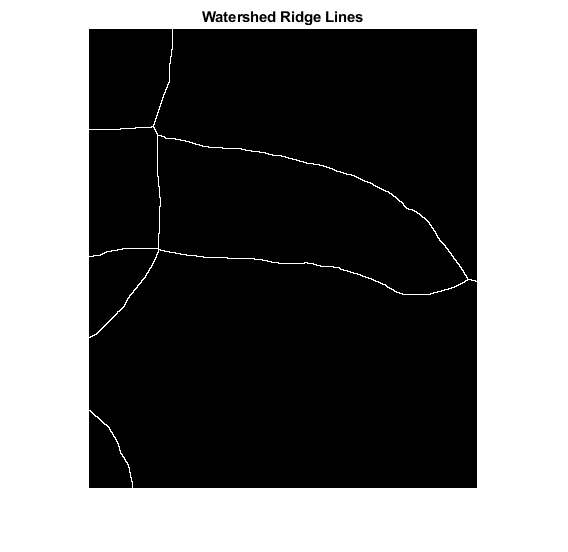

    
%     minimum = extractClosestBlob(minimums, [size(I112,1) / 2 size(I112,2) / 2]);
%     figure
%     imshow(minimum)
%     title('Biggest minimum')
    
    D = bwdist(maximums | minimums);
    DL = watershed(D);
    bgm = DL == 0;
    figure
    imshow(bgm)
    title('Watershed Ridge Lines')

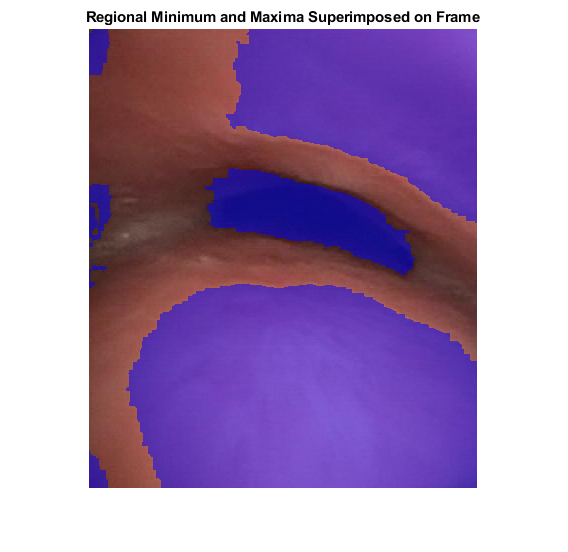

    
    I2 = labeloverlay(I112,minimums | maximums);
    figure
    imshow(I2)
    title('Regional Minimum and Maxima Superimposed on Frame')

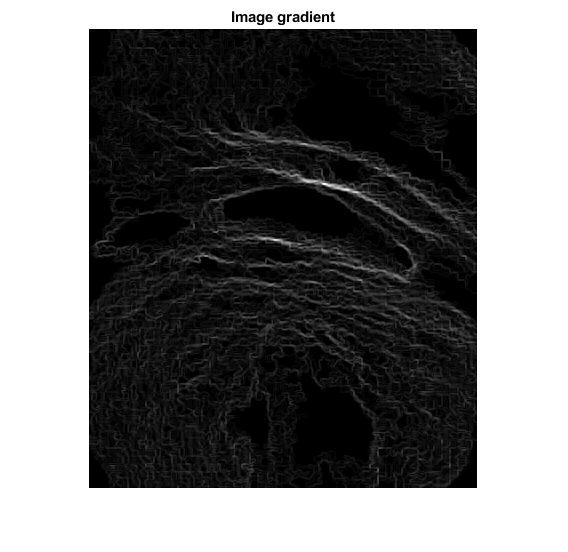

    
%     fgm2 = imclose((minimums | maximums),se);
%     fgm3 = imerode(fgm2,se);
%     fgm4 = bwareaopen(fgm3,20);
%     I3 = labeloverlay(I112,fgm4);
%     figure
%     imshow(I3)
%     title('Modified Regional Minimum and Maxima Superimposed on Frame')
    
    % Gradient of the image
    gmag = imgradient(grayProcessed);
    figure
    imshow(gmag,[]);
    title('Image gradient')

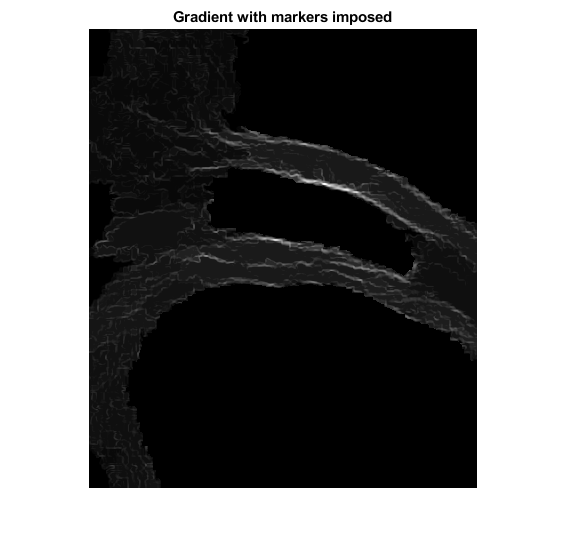

    
    fgm = (minimums | maximums);
    gmag2 = imimposemin(gmag, fgm);
    figure
    imshow(gmag2,[])
    title('Gradient with markers imposed')

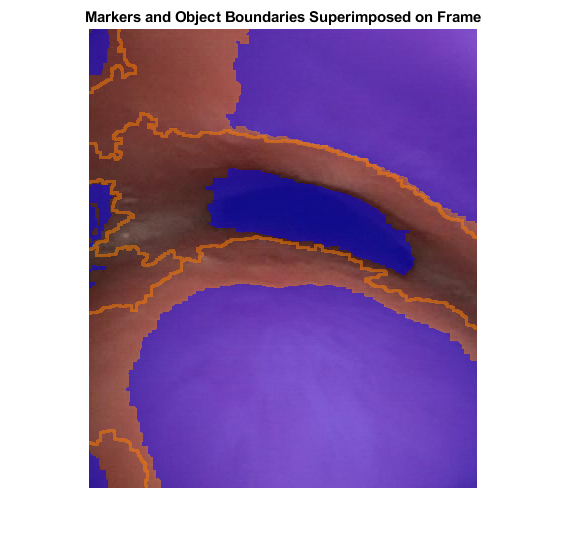

    
    L = watershed(gmag2);
    labels = imdilate(L==0,ones(3,3)) + 2*(minimums | maximums) + 3*fgm;
    I4 = labeloverlay(I112,labels);
    figure
    imshow(I4)
    title('Markers and Object Boundaries Superimposed on Frame')

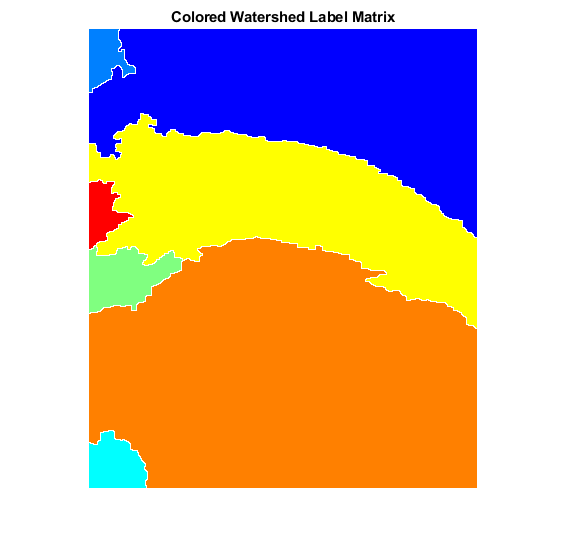

    
    % labeling the watershed results
    Lrgb = label2rgb(L,'jet','w','shuffle');
    figure
    imshow(Lrgb)
    title('Colored Watershed Label Matrix')

    
    % Getting the the value of the labels for the 
    labelValue = L(minimums);
    % Getting the label with maximum ocurrence
%     value = mode(labelValue);
    values = unique(labelValue(:,1))

values = 3×1 uint8 column vector
   2
   3
   6


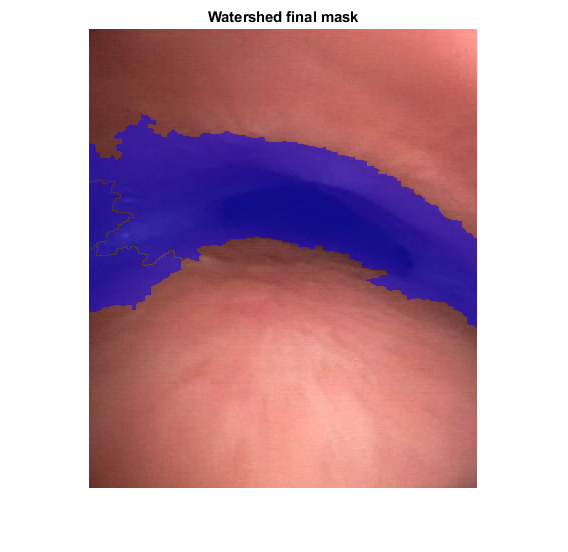

    % Getting the watershed segmentation of the stenosis level
    watershedSegmentation = zeros(size(L,1), size(L,2));
    for i = 1:size(values)
        watershedSegmentation = watershedSegmentation | L == values(i);
    end
    I5 = labeloverlay(I112,watershedSegmentation);
    figure
    imshow(I5)
    title('Watershed final mask')

    
    

% ----------- RGB colorspace -------------------

% numColors = 10;
% [L,centroids] = imsegkmeans(I112,numColors,"NumAttempts",3);
% overlay = labeloverlay(I112,L);
% figure
% imshow(overlay)
% title("Labeled Image RGB")
% 
% R = I112(:,:,1);
% G = I112(:,:,2);
% B = I112(:,:,3);
% 
% wellIx = 0;
% minR = 300;
% minG = 300;
% minB = 300;
% minCount = 0;
% for i = 1:numColors 
%     % Mask applied to input image
%     mask = L == i;
%     cluster = I112.*uint8(mask);
%     figure
%     imshow(cluster)
%     title("RGB Cluster "+i);
%     
%     % Minimum values of ligth intensity for each channel in the cluster
%     auxMinR = min(R(mask > 0));
%     auxMinG = min(G(mask > 0));
%     auxMinB = min(B(mask > 0));
%     
%     % Count the number of channels that has lower values that the current
%     % lowest
%     if minR > auxMinR
%         minCount = minCount + 1;
%     end
%     if minG > auxMinG
%         minCount = minCount + 1;
%     end
%     if minB > auxMinB
%         minCount = minCount + 1;
%     end
%     
%     % If 2 or more channels has less lighting I select it as the well
%     % channel
%     if minCount >= 2
%         wellIx = i;
%         minR = auxMinR;
%         minG = auxMinG;
%         minB = auxMinB;
%     end
%     minCount = 0;
% end
% mask = wellIx
% 
% % Range of values on the green/red spectrum
% maskRrange = [min(R(L == mask)) max(R(L == mask))]
% maskGrange = [min(G(L == mask)) max(G(L == mask))]
% maskBrange = [min(B(L == mask)) max(B(L == mask))]
% 
% J = label2rgb(L,im2double(centroids));
% figure
% imshow(J)
% title("Color Quantized Image")
% 
% showMask = L == wellIx;
% B = L.*uint8(showMask);
% 
% C = labeloverlay(I112,B);
% imshow(C)
% title("Image with cluster "+wellIx+" overlaped")

% --------------- LAB color space ---------------------
% 
% lab_I112= rgb2lab(I112);
% 
% imLuminance = lab_I112(:,:,1);
% ab = lab_I112(:,:,2:3);
% ab = im2single(ab);
% a = ab(:,:,1);
% b = ab(:,:,2);
% pixel_labels = imsegkmeans(ab,numColors,"NumAttempts",3);
% 
% B2 = labeloverlay(I112,pixel_labels);
% figure
% imshow(B2)
% title("Labeled Image a*b*")
% 
% wellIx = 0
% minimalLuminance = 500;
% for i = 1:numColors 
%     % Mask applied to input image
%     mask = pixel_labels == i;
%     cluster = I112.*uint8(mask);
%     figure
%     imshow(cluster)
%     title("Cluster "+i);
%     
%     % Getting the luminance of the mask
%     luminance = imLuminance.*mask;
%     
%     % Minimum value of luminance per cluster
%     maskMinLuminance = min(luminance(luminance > 0));
%     
%     % Storing the ix of the cluster with less luminance
%     if maskMinLuminance < minimalLuminance
%         minimalLuminance = maskMinLuminance;
%         wellIx = i;
%     end
% end
% 
% mask = pixel_labels == wellIx;
% 
% % Range of values on the green/red spectrum
% maskGRRange = [min(a(mask > 0)) max(a(mask > 0))]
% 
% % Range of values on the blue/yellow spectrum
% maskBYRange = [min(b(mask > 0)) max(b(mask > 0))]
% 
% showMask = pixel_labels == wellIx;
% 
% B = pixel_labels .* uint8(showMask);
% 
% C = labeloverlay(I112,B);
% imshow(C)
% title("Image with cluster "+wellIx+" overlaped")

% ------------------------------

% mask1 = pixel_labels == 1;
% cluster1 = I112.*uint8(mask1);
% imshow(cluster1)
% title("Objects in Cluster 1");
% 
% mask2 = pixel_labels == 2;
% cluster2 = I112.*uint8(mask2);
% imshow(cluster2)
% title("Objects in Cluster 2");
% 
% mask3 = pixel_labels == 3;
% cluster3 = I112.*uint8(mask3);
% imshow(cluster3)
% title("Objects in Cluster 3");
% 
% mask4 = pixel_labels == 4;
% cluster4 = I112.*uint8(mask4);
% imshow(cluster4)
% title("Objects in Cluster 4");
% 
% mask5 = pixel_labels == 5;
% cluster5 = I112.*uint8(mask5);
% imshow(cluster5)
% title("Objects in Cluster 5");

% Getting masks luminance
% imLuminance = lab_I112(:,:,1);
% mask1Luminance = imLuminance.*mask1;
% mask2Luminance = imLuminance.*mask2;
% mask3Luminance = imLuminance.*mask3;
% mask4Luminance = imLuminance.*mask4;
% mask5Luminance = imLuminance.*mask5;
% 
% % Minimum values of luminance per mask
% mask1minLuminance = min(mask1Luminance(mask1Luminance > 0))
% mask2minLuminance = min(mask2Luminance(mask2Luminance > 0))
% mask3minLuminance = min(mask3Luminance(mask3Luminance > 0))
% mask4minLuminance = min(mask4Luminance(mask4Luminance > 0))
% mask5minLuminance = min(mask5Luminance(mask5Luminance > 0))
% 
% a = ab(:,:,1);
% b = ab(:,:,2);
% 
% % Range of values of color on the green/red spectrum
% mask1GRRange = [min(a(mask1 > 0)) max(a(mask1 > 0))]
% mask2GRRange = [min(a(mask2 > 0)) max(a(mask2 > 0))]
% mask3GRRange = [min(a(mask3 > 0)) max(a(mask3 > 0))]
% mask4GRRange = [min(a(mask4 > 0)) max(a(mask4 > 0))]
% mask5GRRange = [min(a(mask5 > 0)) max(a(mask5 > 0))]
% 
% % Range of values of color on the blue/yellow spectrum
% mask1BYRange = [min(b(mask1 > 0)) max(b(mask1 > 0))]
% mask2BYRange = [min(b(mask2 > 0)) max(b(mask2 > 0))]
% mask3BYRange = [min(b(mask3 > 0)) max(b(mask3 > 0))]
% mask4BYRange = [min(b(mask4 > 0)) max(b(mask4 > 0))]
% mask5BYRange = [min(b(mask5 > 0)) max(b(mask5 > 0))]
% 
% [maxLuminance, maxIx] = max([mask1minLuminance mask2minLuminance ...
%     mask3minLuminance mask4minLuminance mask5minLuminance]);
% [minLuminance, minIx] = min([mask1minLuminance mask2minLuminance ...
%     mask3minLuminance mask4minLuminance mask5minLuminance]);
% 
% showMask = pixel_labels == minIx;
% 
% B = pixel_labels .* uint8(showMask);
% 
% C = labeloverlay(I112,B);
% imshow(C)
% title("Labeled Image with Additional Pixel Information")
% -----------------------------

% cc = imstats(I112,'mean','median','mode','modecolor','modefuzzy','moderange','nmost',10);
% % use those stats to construct a swatch chart for single-output stats
% labels = {'mean','median','mode','modecolor','modefuzzy'};
% sz = imsize(I112,2);
% ntiles = (numel(labels));
% tilesz = [round(sz(1)/ntiles) 100];
% block1 = zeros([tilesz 3 ntiles],'uint8');
% for k = 1:ntiles
%     thistile = colorpict([tilesz 3],cc(k,:),'uint8'); % colored swatch
%     thislabel = im2uint8(textim(labels{k},'ibm-iso-16x9')); % text label image
%     thistile = im2uint8(imstacker({thislabel thistile},'padding',0)); % match geometry
%     block1(:,:,:,k) = mergedown(thistile,1,'lineardodge'); % blend label and swatch
% end
% block1 = imtile(block1,[ntiles 1]); % vertically arrange tiles
% block1 = imresize(block1,[sz(1) tilesz(2)]); % make sure it's the right size
% % create another chart for moderange's multiple outputs
% ntiles = (size(cc,1)-ntiles);
% tilesz = [round(sz(1)/ntiles) 100];
% block2 = zeros([tilesz 3 ntiles],'uint8');
% for k = 1:ntiles
%     thistile = colorpict([tilesz 3],cc(k+4,:),'uint8'); % colored swatch
%     thislabel = im2uint8(textim(num2str(k),'ibm-iso-16x9')); % text label image
%     thistile = im2uint8(imstacker({thislabel thistile},'padding',0)); % match geometry
%     block2(:,:,:,k) = mergedown(thistile,1,'lineardodge'); % blend label and swatch
% end
% block2 = imtile(block2,[ntiles 1]); % vertically arrange tiles
% block2 = imresize(block2,[sz(1) tilesz(2)]); % make sure it's the right size
% % show the combined images
% imshow([I112 block1 block2])


function [mask, clusterRRange, clusterGRange, clusterBRange] = kmeansRGBSegmentation(frame, k, flagOuterMarks)

    % Separating the 3 different dimensions
    R = frame(:,:,1);
    G = frame(:,:,2);
    B = frame(:,:,3);
    
    % Applying kmeans
    [labels, centroids]= imsegkmeans(frame,k,"NumAttempts",3);
        
%     C = labeloverlay(frame,labels);
%     figure
%     imshow(C)
%     title("Labeled Image RGB")
    
    minR = 300; % Red channel minimum intensity 
    minG = 300; % Green channel minimum intensity 
    minB = 300; % Blue channel minimum intensity 
    maxR = 0; % Red channel maximum intensity 
    maxG = 0; % Green channel maximum intensity 
    maxB = 0; % Blue channel maximum intensity
    ix = 0; % Index of the cluster to return
    count = 0;
    for i = 1:k 
        % Mask applied to input image
        mask = labels == i;
%         cluster = frame.*uint8(mask);
%         figure
%         imshow(cluster)
%         title("RGB Cluster "+i);
        
        if flagOuterMarks == 0
            % Minimum values of ligth intensity for each channel in the cluster
            auxMinR = min(R(mask > 0));
            auxMinG = min(G(mask > 0));
            auxMinB = min(B(mask > 0));
            
            % Count the number of channels that has lower values that the current
            % lowest
            if minR > auxMinR
                count = count + 1;
            end
            if minG > auxMinG
                count = count + 1;
            end
            if minB > auxMinB
                count = count + 1;
            end
            
            % If 2 or more channels has less lighting I select it as the well
            % channel
            if count >= 2
                ix = i;
                minR = auxMinR;
                minG = auxMinG;
                minB = auxMinB;
            end
        else
            % Minimum values of ligth intensity for each channel in the cluster
            auxMaxR = max(R(mask > 0));
            auxMaxG = max(G(mask > 0));
            auxMaxB = max(B(mask > 0));
            
            % Count the number of channels that has lower values that the current
            % lowest
            if maxR < auxMaxR
                count = count + 1;
            end
            if maxG < auxMaxG
                count = count + 1;
            end
            if maxB < auxMaxB
                count = count + 1;
            end
            
            % If 2 or more channels has less lighting I select it as the well
            % channel
            if count >= 2
                ix = i;
                maxR = auxMaxR;
                maxG = auxMaxG;
                maxB = auxMaxB;
            end
        end
        
        count = 0;
    end
    mask = [];
    % Mask of the resulting cluster
    if flagOuterMarks == 0
        mask = labels == ix;
    else
        mask = labels == ix;
    end
    
    % Range of values on the Red spectrum
    clusterRRange = [min(R(mask > 0)) max(R(mask > 0))];
    % Range of values on the Green spectrum
    clusterGRange = [min(G(mask > 0)) max(G(mask > 0))];
    % Range of values on the Blue spectrum
    clusterBRange = [min(G(mask > 0)) max(G(mask > 0))];
    
%     B = labels .* uint8(mask);
%     C = labeloverlay(frame,B);
%     imshow(C)
%     title("Labeled Image with Additional Pixel Information")
end

function binaryImage = extractClosestBlob(binaryImage, point)
    try
      % Get all the Centroids
      [labeledImage, numberOfBlobs] = bwlabel(binaryImage);
      blobStats = regionprops(labeledImage, 'Centroid');
      allCentroids = [blobStats.Centroid];
      allCentroids = reshape(allCentroids,2,[]).';
        
      % Get the closest Blob to the point
      [k, dist] = dsearchn(point,allCentroids);
      [~, ixStats] = min(dist);
      
      % Extract the blob using ismember().
      biggestBlob = ismember(labeledImage, ixStats);
      % Convert from integer labeled image into binary (logical) image.
      binaryImage = biggestBlob > 0;
      
    catch ME
      errorMessage = sprintf('Error in function extractClosestBlob().\n\nError Message:\n%s', ME.message);
      fprintf(1, '%s\n', errorMessage);
      uiwait(warndlg(errorMessage));
    end
end

function openClosedImage = openCloseByReconstruction(frame)    
    se = strel('disk',20);
    frameOpen = imopen(frame,se);
%     figure
%     imshow(frameOpen)
%     title('Opening')
    
    frameErode = imerode(frame,se);
    frameObR = imreconstruct(frameErode,frame);
%     figure
%     imshow(frameObR)
%     title('Opening-by-Reconstruction')
    
    frameOpCl = imclose(frameOpen,se);
%     figure
%     imshow(frameOpCl)
%     title('Opening-Closing')
    
    frameObRDilated = imdilate(frameObR,se);
    frameOCRecon = imreconstruct(imcomplement(frameObRDilated),imcomplement(frameObR));
    openClosedImage = imcomplement(frameOCRecon);
%     figure
%     imshow(openClosedImage)
%     title('Opening-Closing by Reconstruction')
end